# Linear Control Design 2 - Fall 2021 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E21) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**All exercises are equally weighted towards the overall assessment of the examination.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E21'

Exam = 'LCD2 E21'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Output feedback control of a test mass accelerometer

A test mass accelerometer is a measuring system utilized to measured vertical accelerations in e.g. vehicles. The figure below shows a simplified schematic of such device.

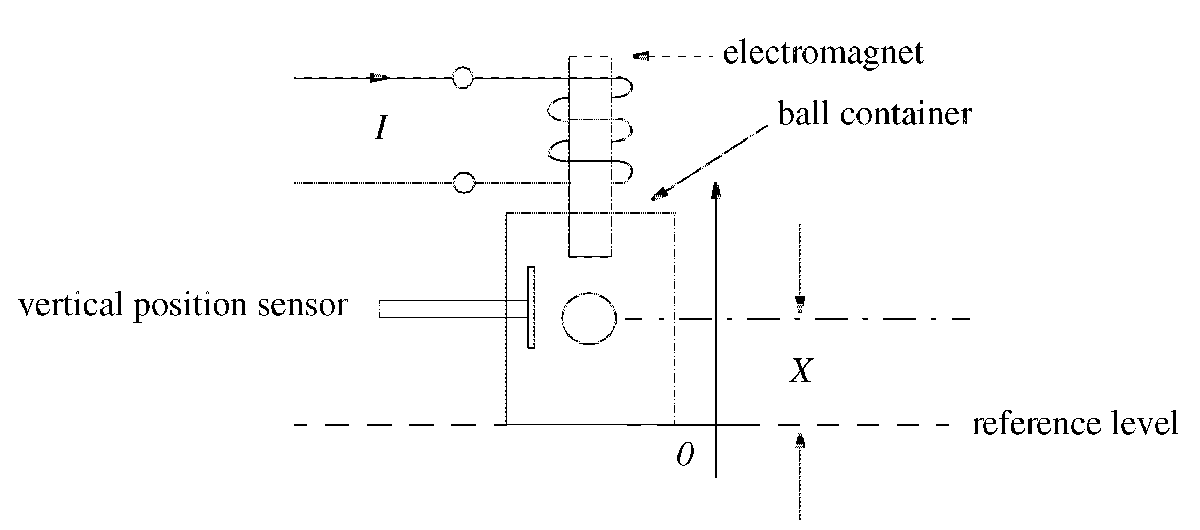

The test mass is a steel ball with a mass $m = 10\mathrm{g}$. The ball is held floating in a magnetic field by the electromagnet above it. The vertical position of the ball is measured by a position sensor.

The electromagnetic force that keeps the ball floating is given by


$$F_{em}(X,I) = 1.805\times10^3X^2 + 14.44XI - 6.498X + 0.02888I^2 + 0.374I - 0.1742$$


where $X$is the ball position (in meters) in relation to the reference point and $I$ is the current (in Amperes).

The ball is also influenced by the air resistance. The force that air resistance exerts on the ball is


$$F_{ar}(V) = -V(c_1 + c_2|V|)$$


where $c_1 = 1.55\times10^{-6}\mathrm{N}(m/s)$, $c_2 = 2.2\times 10^{-4}\mathrm{N(m/s)^2} $ and the ball's velocity $V$is expressed in $m/s$.

The accelerometer is under the influence of an external vertical acceleration $A$. The nonlinear model describing the motion of the ball reads


$$\frac{d^2X}{dt^2} = \frac{1}{m}F_{ar}(V)+\frac{1}{m}F_{em}(X,I) + A - g$$


where $g = 9.81\mathrm{m/s^2}$ is the acceleration of gravity.

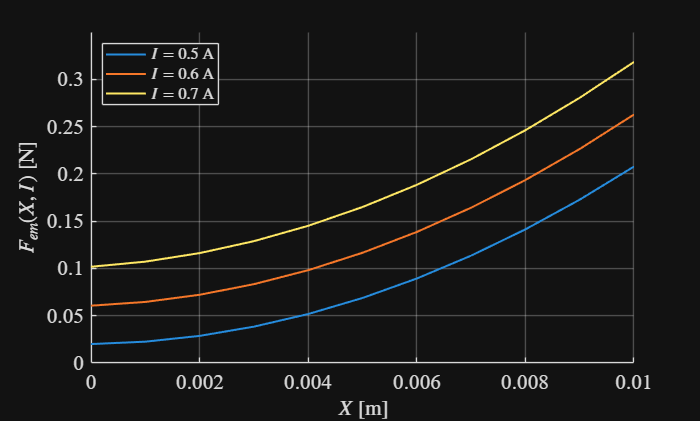

% Simulator parameters (RG)
SIM_TIME = 1; 
STEP_SIZE = 0.0001;
% Change with the name of the model you are using
SIMULINK_FILENAME = 'TestMassAccelerometer_NonlinearModel_Simulink2020b';

% Model paramters (RG)
m = 0.01; % mass in kilograms
c1 = 1.55*10^-6; % N*m/s
c2 = 2.2*10^-4; % N*m^2/s^2
% Coefficients of the electromagnetic force
f1 = 1.805*10^3; 
f2 = 14.44;
f3 = 6.498;
f4 = 0.02888;
f5 = 0.3740;
f6 = 0.1742;
% --------------------------------------------
g = 9.81; % m/s^2
A = 0; % m/s^2

% Electromagnetic force for different values of control current I (RG)
X = (0:0.001:0.01)'; % mass displacement range [m]
I0 = [0.5 0.6 0.7]; % control current [A]
for ii = 1:length(I0)
    F_em(:,ii) = f1*X.^2 + f2*X.*I0(ii) - f3*X + f4*I0(ii).^2 + f5*I0(ii) - f6;
end

figure, h1 = axes; set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(X,F_em,'LineWidth',1.5)
ylabel('$F_{em}(X,I)$ [N]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$X$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
leg = legend('$I = 0.5$ A','$I = 0.6$ A','$I = 0.7$ A','Location','NorthWest');
set(leg,'FontName','times','FontSize',12,'Interpreter','latex')

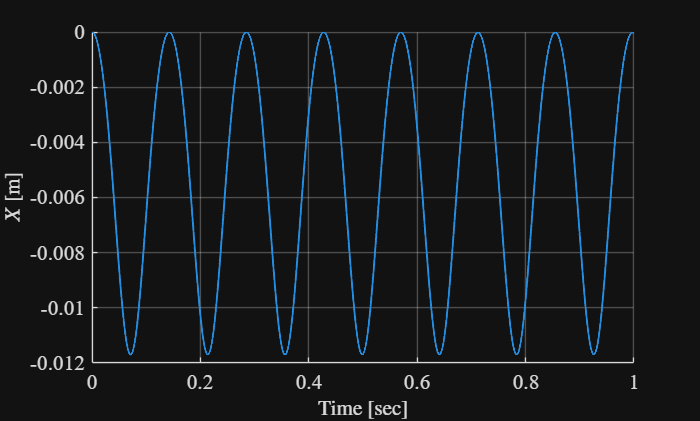

% Test the provided nonlinear model (RG)
time = (0:STEP_SIZE:SIM_TIME)';
x0 = zeros(2,1); % initial condition x0 = [X,V]'
I0 = 0.5; % test current through the electromagnet [A]
I = I0*ones(length(time),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time I])

% Plot simulation result
t = logsout.getElement(1).Values.Time;
X = logsout.getElement(1).Values.Data;
V = logsout.getElement(2).Values.Data;

figure, h2 = axes; set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(t,X,'LineWidth',1.5)
ylabel('$X$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

## Operating point and linearization

**Problem 1 (2 points) **Determine the operating point associated with a nominal verical displacement of the mass $X_n = 2.5\mathrm{mm}$ when the external vertical acceleration $A=0$. Linearize the system around the operatig point.

% Your solution goes here
x0 = [0.0025 0]';
y0 = 0.0025;
[xss,uss,yss,dx] = trim(SIMULINK_FILENAME,x0,[],y0,[1 1],[],1)

xss =     0.0025
    0.0000


uss = 0.6466

yss = 0.0025

dx = 1.0e-11 *

    0.0000
   -0.6674


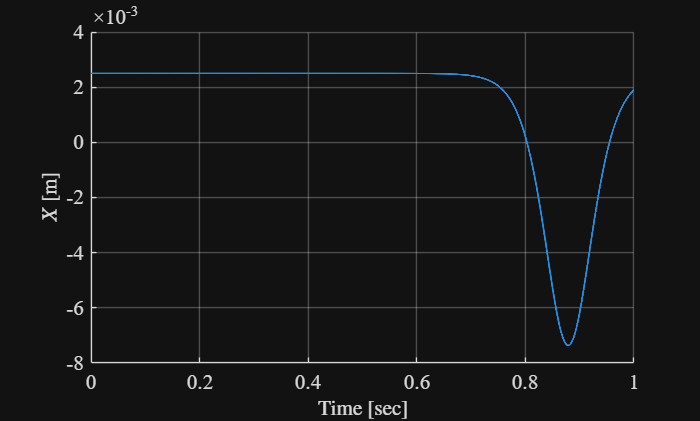

Xss = xss(1);
Vss = xss(2);
Iss = uss;
I = Iss*ones(length(time),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time I])

% Plot simulation result
t = logsout.getElement(1).Values.Time;
X = logsout.getElement(1).Values.Data;
V = logsout.getElement(2).Values.Data;

figure, h3 = axes; set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(t,X,'LineWidth',1.5)
ylabel('$X$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

% Linearization of the nonlinear system
[Aol,Bol,Col,Dol] = linmod(SIMULINK_FILENAME,xss,uss)

Aol = 1.0e+03 *

         0    0.0010
    1.1865   -0.0000


Bol =          0
   44.7450


Col =      1     0


Dol = 0

## Stability analysis

**Problem 2 (2 points)** Assess the internal and external stability of the linear system.

% Your solution goes here
lambda_ol = eig(Aol)

lambda_ol =    34.4448
  -34.4450


disp('One pole has positive real part => System is unstable')

One pole has positive real part => System is unstable


[num, den] = ss2tf(Aol,Bol,Col,Dol);
G = minreal(tf(num, den));
eigenvalues = pole(G)

eigenvalues =   -34.4450
   34.4448


disp('One pole has positive real part => System is unstable')

One pole has positive real part => System is unstable


## Control system design for measurement of external acceleration

The test mass accelerometer in opern loop is not capable of providing a measurement of the external vertical acceleration $A$. In order to enable the measuring device to provide such measurement a control system need to be designed.

Closed-loop system requirements

1) The position $X$ of the test mass is regulated to its nominal value $X_n$ despite step changes in the external vertical acceleration $A$.

2) For a step change in the external vertical acceleration $A$ equal to $0.25g$ at a time $t = t_{step}$ the position $X$ is regulated back to its nominal value $X_n$ with

        a) a maximum 20% deviation from its steady state value during the transient part of the response

        b) settling time between 50 and 75 milliseconds

Please refer to the following figure for a clear definition of the quantities described in the requirements. **IMPORTANT** The response shown in the figure (blue curve) serves only to display quantities of interest for the design requirements; therefore it does not necessarily represent the expected system behaviour.

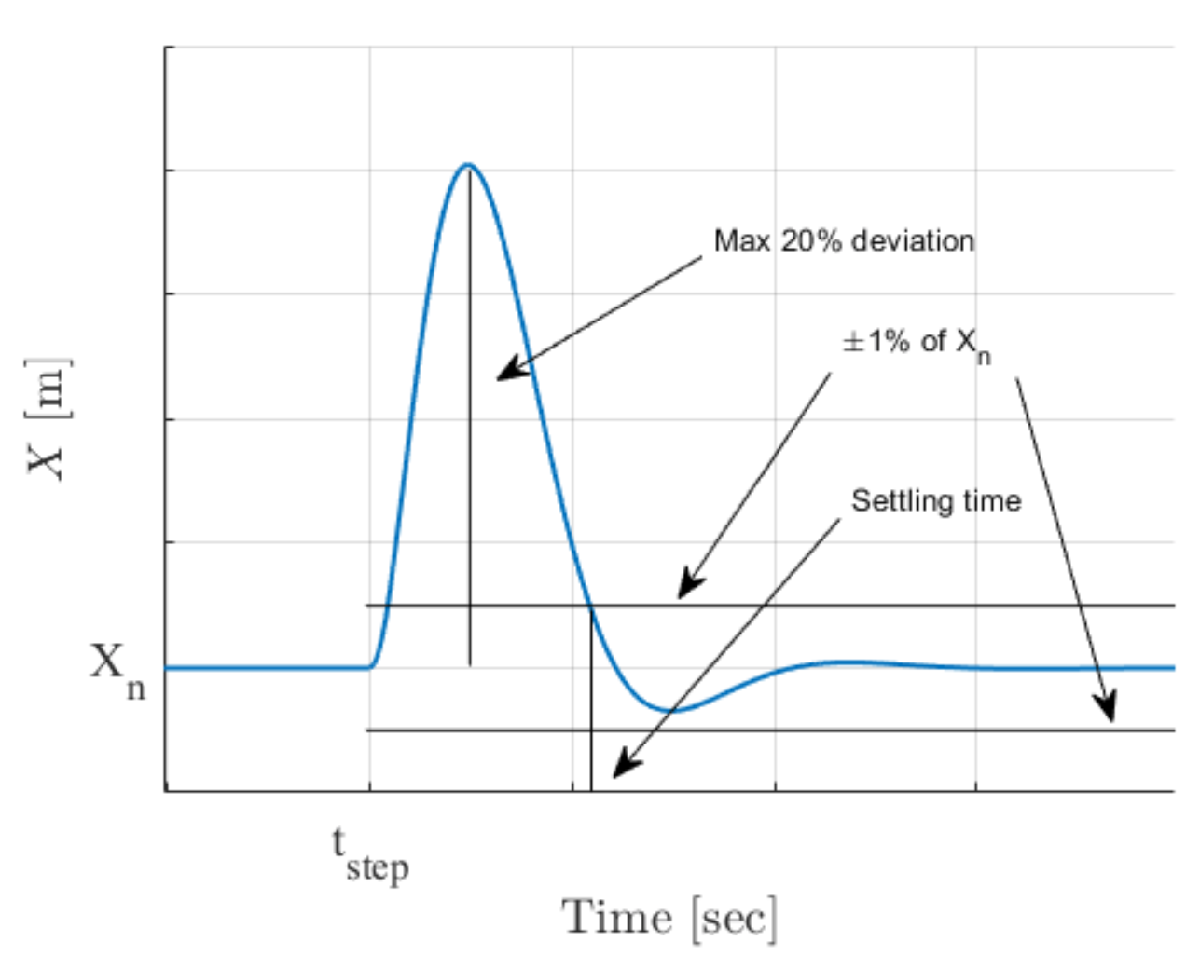

**Problem 3 (6 points)** Under the assumption that the state is fully accessible **design a discrete time optimal controller** that meets the aforementioned specifications on the nonlinear system.

% Your solution goes here
% Controllability test
Mc = ctrb(Aol,Bol);

if rank(Mc) == size(A,1)
    disp('Open loop linear system is controllable')
else
    disp('Open loop linear system is not controllable')
end

Open loop linear system is not controllable


% Discretize the open loop system
Ts = 0.005; % approximately 10 times smaller than the desired settling time
[Fol,Gol] = c2d(Aol,Bol,Ts)

Fol =     1.0149    0.0050
    5.9616    1.0149


Gol =     0.0006
    0.2248


% Compute the reachability matrix and check if the system is reachable
Mr = ctrb(Fol,Gol);
if rank(Mr) == size(Fol,1)
    disp('The open loop system is reachable')
end

The open loop system is reachable


% Adding integral action Cf. Lecture 13
F_aug = [Fol zeros(2, 1); -Ts*Col 1];
G_aug = [Gol; 0];
C_aug = [Col 0];

Q = diag([10 0.001 400000]);
R = 0.005;

[K_opt,~,lambda_cl_dt] = dlqr(F_aug,G_aug,Q*Ts,R*Ts);
lambda_cl_dt = abs(lambda_cl_dt) % discrete time / Z-domain

lambda_cl_dt =     0.8132
    0.8132
    0.6760


% Splitting K_opt into normal and integral parts
K_opt_fs = K_opt(1:2);
K_opt_integral = -K_opt(3);
x0_int = 0;

% Closed-loop linear system
Fcl = F_aug - G_aug*K_opt;
% Discrete time eigenvalues
lambda_cl_dt = eig(Fcl)

lambda_cl_dt =    0.7789 + 0.2336i
   0.7789 - 0.2336i
   0.6760 + 0.0000i


% Equivalent continuous time eigenvalues
lambda_cl_ct = 1/Ts*log(lambda_cl_dt);
disp('The fastest closed-loop dynamics is')

The fastest closed-loop dynamics is


disp(strcat(num2str(max(abs(lambda_cl_ct))),'rad/s'))

78.3252rad/s


disp('The damping ratio is')

The damping ratio is


zeta_cl = -real(lambda_cl_ct(2))/abs(lambda_cl_ct(2));
disp(num2str(zeta_cl))

0.57879



Fcl = F_aug - G_aug*K_opt;
Bdol = [0; 1]; % input matrix for the "disturbance" acceleration
[~,Gdol] = c2d(Aol,Bdol,Ts);
Br = [0; 0; Ts]; % reference input matrix
Gcl = [Br [Gdol;0]];

sys_cl_dt = ss(Fcl, Gcl, C_aug, [], Ts);

tlin = (0:Ts:1)';
ulin = [zeros(length(tlin),1) [zeros((length(tlin)-1)/2,1);g*ones((length(tlin)-1)/2+1,1)]];
x0lin = zeros(3,1);
[ylin,tlin,xlin] = lsim(sys_cl_dt,ulin,tlin,x0lin);

overshoot_lin = 100*(Xss - min(Xss+xlin(:,1)))/Xss;
disp(['The overshoot of the linear response is ', num2str(overshoot_lin), '%'])

The overshoot of the linear response is 3.0403%


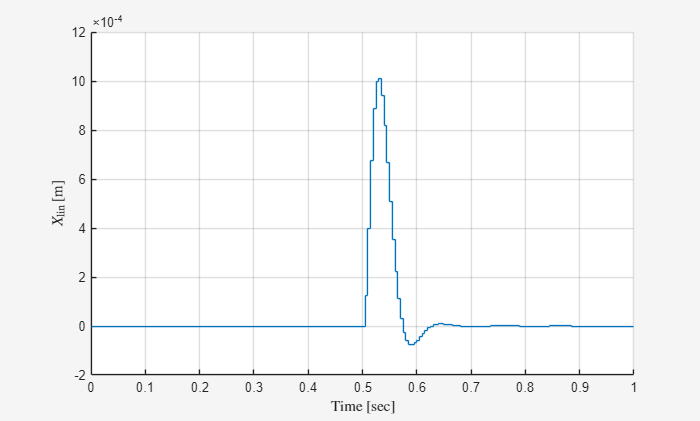

figure()
hold on, grid on
stairs(tlin,ylin)
ylabel('$X_{\mathrm{lin}}$ [m]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')
theme("light")

**Problem 4** **(2 points)** Implement the discrete time optimal controller in the Simulink model of the nonlinear system, and evalute the closed-loop system performance against the given requirements, when the sytem is subject to the step change in the external vertical acceleration $A$ of $0.25g$.

% Your solution goes here
% Check if the requirements are fulfilled
SIMULINK_FILENAME = 'TestMassAccelerometer_NonlinearModel_LQR_Simulink2017';

X_ref = Xss;
STEP_TIME = 0.5;
A0 = 0;
A1 = 0.25*g;
SIM_TIME = 1;
STEP_SIZE = 0.0001;
sim(SIMULINK_FILENAME,SIM_TIME)

% Plot simulation result
timeCT = logsout.getElement(3).Values.Time;
X = logsout.getElement(3).Values.Data;
V = logsout.getElement(4).Values.Data;
timeDT = logsout.getElement(2).Values.Time;
int_ctrl = logsout.getElement(2).Values.Data;
fs_ctrl = -logsout.getElement(1).Values.Data;
ctrl_inp = logsout.getElement(7).Values.Data;

settling_p1pct = Xss*1.01;
settling_m1pct = Xss*0.99;
overshoot = 100*(max(X)- Xss)/Xss;
disp(['The overshoot of the linear response is ', num2str(overshoot), '%'])

The overshoot of the linear response is 10.1613%


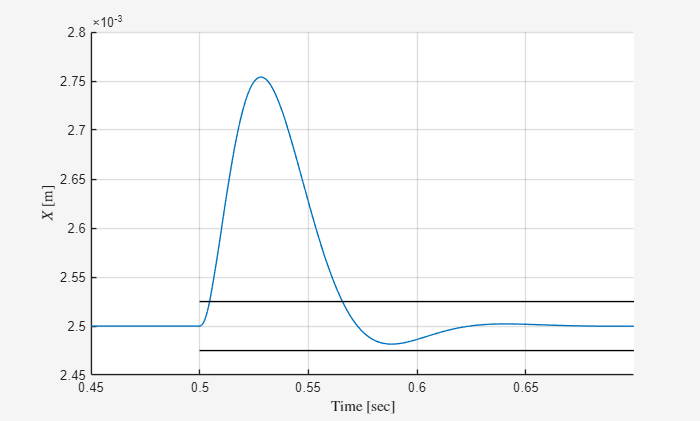

figure()
hold on, grid on
plot(timeCT,X)
line([timeCT(0.5/STEP_SIZE) timeCT(round(0.7/STEP_SIZE))],[settling_p1pct settling_p1pct],'Color','k')
line([timeCT(0.5/STEP_SIZE) timeCT(round(0.7/STEP_SIZE))],[settling_m1pct settling_m1pct],'Color','k')
xlim([timeCT(0.45/STEP_SIZE) timeCT(round(0.7/STEP_SIZE))])
ylabel('$X$ [m]','Interpreter','latex')
xlabel('Time [sec]','Interpreter','latex')
theme("light")

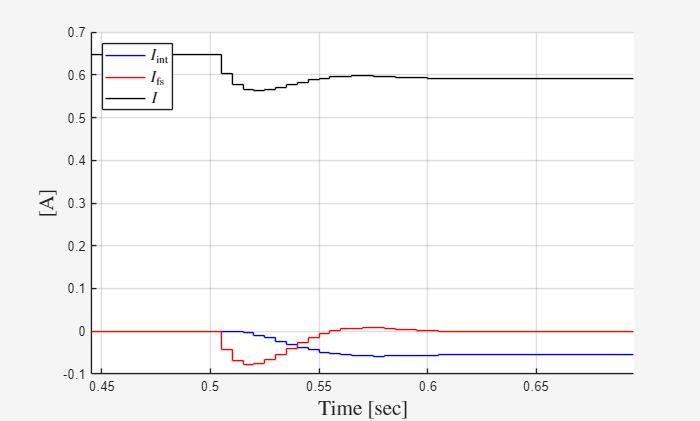

figure()
hold on, grid on
stairs(timeDT,int_ctrl,'b')
stairs(timeDT,fs_ctrl,'r')
stairs(timeDT,ctrl_inp,'k')
xlim([timeDT(0.45/Ts) timeDT(0.7/Ts)])
ylabel('[A]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
leg2 = legend('$I_{\mathrm{int}}$','$I_{\mathrm{fs}}$','$I$','Location','NorthWest');
set(leg2,'FontName','times','FontSize',12,'Interpreter','latex')
theme("light")

## Observer design for estimation of the external acceleration

In order to determine the unknown acceleration $A$ acting on the measuring device a state estimator in the form of a Kalman filter can be employed.

The position measurement is affected by white noise $w$ with zero mean and noise intensity $V_w = 1\times10^{-10}$, i.e.


$$y = X + w$$


**Problem 5 (6 points)** Under the assumption that the exteral vertical acceleration is constant, **design a discrete time Kalman filter** able to reconstruct the state vector $x = [X,V]^\mathrm{T}$ and the unknown constant acceleration $A$. Note: "reconstruct the state vector", add A as a state.

% Your solution goes here
F_kf = [Fol Gdol;0 0 1]; % Gdol (disturbance matrix Bv) gets added, as disturbance is now a state
G_kf = [Gol; 0];
Bv_kf = [0; 0; 1]; % continuous time process noise input matrix
Gv_kf = eye(3); % discrete time process noise input matrix
C_kf = [Col 0];

Q = Bv_kf * 50 * Bv_kf' * Ts; % Multiply with Ts because it's sensor noise
Vw = 10^(-10) / Ts; % Dividing with Ts because it's process noise

% Check observability
Mo = obsv(F_kf,C_kf);
if rank(Mo) == size(F_kf,1)
    disp('The open loop system is observable')
end

The open loop system is observable


[L_KF,P,Z,lambda_ee_dt] = dlqe(F_kf, Gv_kf, C_kf, Q, Vw);
abs(lambda_ee_dt) % Stable

ans =     0.7915
    0.7915
    0.6265


lambda_kf_ct = 1/Ts*log(lambda_ee_dt);
disp(['The slowest estimation error dynamics is ', strcat(num2str(min(abs(lambda_kf_ct)))), ' rad/s'])

The slowest estimation error dynamics is 86.9539 rad/s


if min(abs(lambda_kf_ct)) > max(abs(lambda_cl_ct))
    disp('Observer dynamics faster than controller dynamics --> OK!')
else
    disp('Observer dynamics slower than controller dynamics --> NOT OK!')
end

Observer dynamics faster than controller dynamics --> OK!


**Problem 6 (4 points) **Implement the discrete time Kalman filter in the Simulink diagram of the closed-loop system, and assess the estimation performance of the Kalman filter when tested on the nonlinear system together with the control system designed in Problem 3, both in stationary conditions and in the presence of the step change in the external vertical acceleration $A$ of $0.25g$.

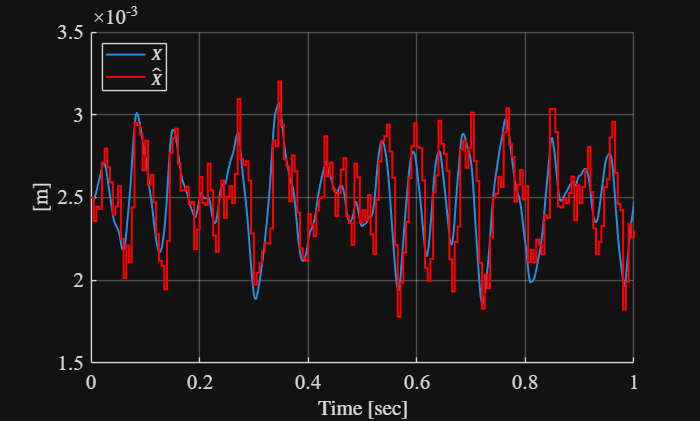

% Your solution goes here
SIMULINK_FILENAME = 'TestMassAccelerometer_NonlinearModel_LQR_KF_Simulink2017';

% Simulate steady state
X_ref = Xss;
x0_hat = zeros(3,1);
STEP_TIME = 0.5;
A0 = 0;
A1 = 0;
SIM_TIME = 1;
STEP_SIZE = 0.001;
sim(SIMULINK_FILENAME,SIM_TIME)

% Plot simulation result
timeCT = logsout.getElement(3).Values.Time;
X = logsout.getElement(3).Values.Data;
V = logsout.getElement(4).Values.Data;
A = logsout.getElement(10).Values.Data;
timeDT = logsout.getElement(2).Values.Time;
int_ctrl = logsout.getElement(2).Values.Data;
fs_ctrl = -logsout.getElement(1).Values.Data;
ctrl_inp = logsout.getElement(9).Values.Data;
X_hat = logsout.getElement(8).Values.Data(:,1)+Xss;
V_hat = logsout.getElement(8).Values.Data(:,2);
A_hat = logsout.getElement(8).Values.Data(:,3);
inno = logsout.getElement(6).Values.Data;

figure, h7 = axes; set(h7,'FontName','times','FontSize',16)
hold on, grid on
plot(timeCT,X,'LineWidth',1.5)
stairs(timeDT,X_hat,'r','LineWidth',1.5)
ylabel('[m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
leg3 = legend('$X$','$\hat{X}$','Location','NorthWest');
set(leg3,'FontName','times','FontSize',12,'Interpreter','latex')

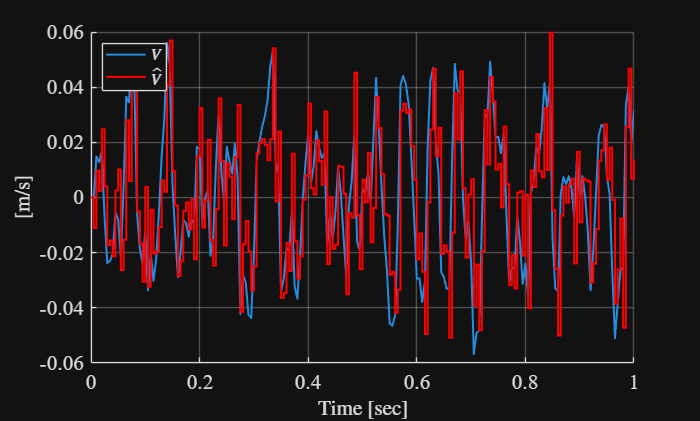

figure, h8 = axes; set(h8,'FontName','times','FontSize',16)
hold on, grid on
plot(timeCT,V,'LineWidth',1.5)
stairs(timeDT,V_hat,'r','LineWidth',1.5)
ylabel('[m/s]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
leg4 = legend('$V$','$\hat{V}$','Location','NorthWest');
set(leg4,'FontName','times','FontSize',12,'Interpreter','latex')

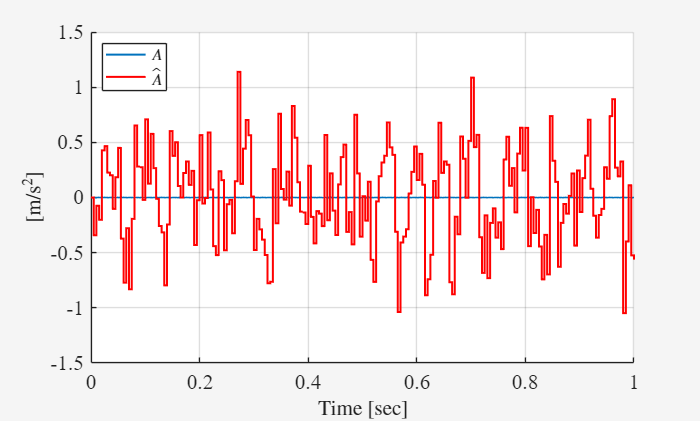

figure, h9 = axes; set(h9,'FontName','times','FontSize',16)
hold on, grid on
plot(timeCT,A,'LineWidth',1.5)
stairs(timeDT,A_hat,'r','LineWidth',1.5)
ylabel('[m/s$^2$]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
leg5 = legend('$A$','$\hat{A}$','Location','NorthWest');
set(leg5,'FontName','times','FontSize',12,'Interpreter','latex')
theme("light")

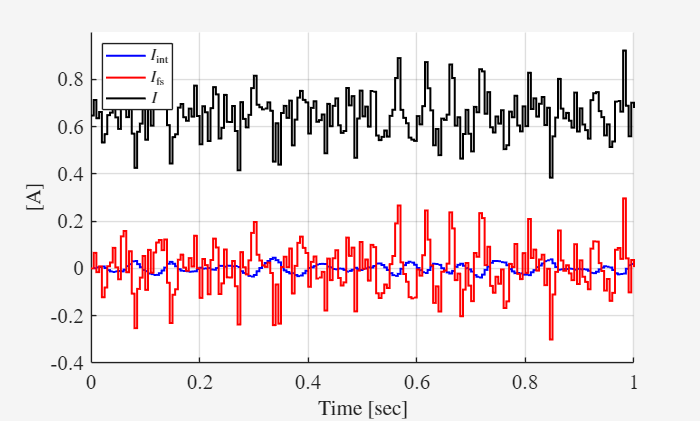


figure, h10 = axes; set(h10,'FontName','times','FontSize',16)
hold on, grid on
stairs(timeDT,int_ctrl,'b','LineWidth',1.5)
stairs(timeDT,fs_ctrl,'r','LineWidth',1.5)
stairs(timeDT,ctrl_inp,'k','LineWidth',1.5)
ylabel('[A]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
leg10 = legend('$I_{\mathrm{int}}$','$I_{\mathrm{fs}}$','$I$','Location','NorthWest');
set(leg10,'FontName','times','FontSize',12,'Interpreter','latex')
theme("light")